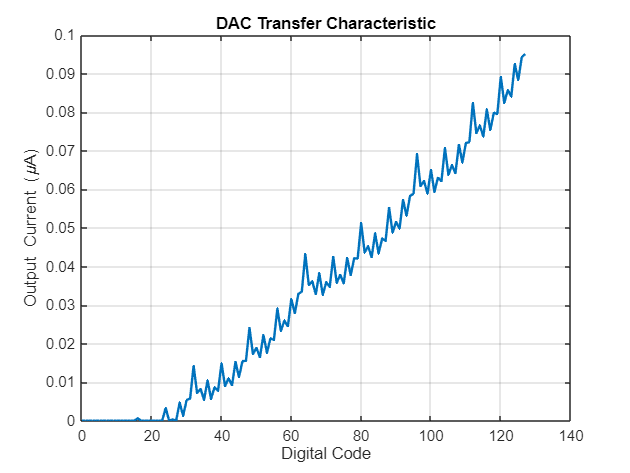

%% analyze_dac_from_ngspice.m
% Analyze DAC linearity from Ngspice text data (code vs. Iout)
clear; clc; close all;

%% === Load Data ===
% Read file (space-delimited, skip first line if it contains text)
data = readmatrix('test_dac5.txt');

% The file columns are:
% 1: some constant (ignore)
% 2: code
% last-but-one: i(Viout)
code = data(:,2);
Iout = data(:,end-1); % current output column

% Remove any duplicates or NaNs just in case
valid = ~isnan(code) & ~isnan(Iout);
code = code(valid);
Iout = Iout(valid);

% Sort by code (Ngspice might not export in order)
[code, idx] = sort(code);
Iout = Iout(idx);

%% === Basic Parameters ===
N = ceil(log2(length(code))); % estimate DAC bits (≈7)
I_min = Iout(1);
I_max = Iout(end);
I_LSB = (I_max - I_min) / (2^N - 1);

%% === Ideal Reference Line ===
I_ideal = I_min + I_LSB * (code - code(1));

%% === DNL Calculation ===
delta_I = diff(Iout);        % actual step sizes
DNL = (delta_I / I_LSB) - 1; % step error in LSBs

%% === INL Calculation ===
INL = (Iout - I_ideal) / I_LSB;

%% === Plots ===

% Transfer characteristic
figure;
plot(code, Iout * 1e6, 'LineWidth', 1.6);
xlabel('Digital Code');
ylabel('Output Current (\muA)');
title('DAC Transfer Characteristic');
grid on;

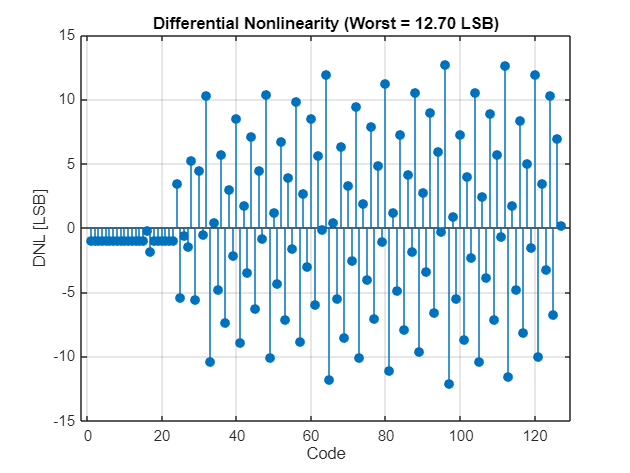


% DNL
figure;
stem(code(2:end), DNL, 'filled');
xlabel('Code');
ylabel('DNL [LSB]');
title(sprintf('Differential Nonlinearity (Worst = %.2f LSB)', max(abs(DNL))));
grid on;

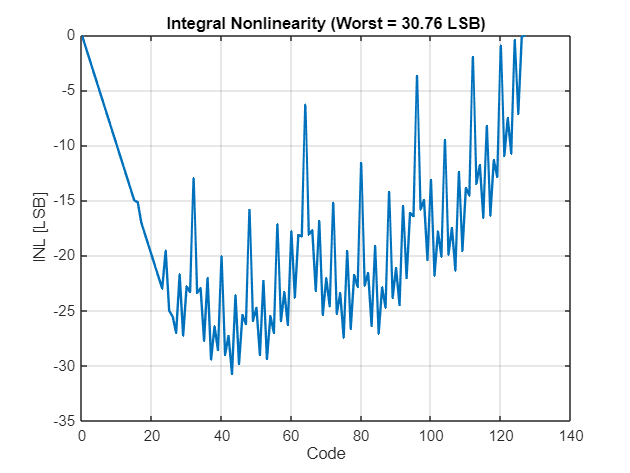


% INL
figure;
plot(code, INL, 'LineWidth', 1.6);
xlabel('Code');
ylabel('INL [LSB]');
title(sprintf('Integral Nonlinearity (Worst = %.2f LSB)', max(abs(INL))));
grid on;


%% === Print Summary ===
fprintf('--- DAC Linearity Summary ---\n');

--- DAC Linearity Summary ---


fprintf('Number of bits: %.0f\n', N);

Number of bits: 7


fprintf('LSB size: %.3e A\n', I_LSB);

LSB size: 7.491e-10 A


fprintf('Worst-case DNL: %.2f LSB\n', max(abs(DNL)));

Worst-case DNL: 12.70 LSB


fprintf('Worst-case INL: %.2f LSB\n', max(abs(INL)));

Worst-case INL: 30.76 LSB
